clear;
M = 264.5866;
m = 9.1747;
l = 2.5849;
g = 9.81;
f = 0;

A = [0, 1, 0, 0;
    0, 0, (3*g*m)/(m+4*M), 0;
    0, 0, 0, 1;
    0, 0, (6*g*(m+M))/(l*(m+4*M)), 0];

B = [0; 4/(m+4*M); 0; 6/(l*(m+4*M))];
C = [1, 0, 0, 0; 0, 0, 1, 0];
C_ = C(2,:);
D = [0; 6/(l*(m+4*M)); 0; (12*(m+M))/(l^2*m*(m+4*M))];



x_0 = [0.01; 0.01; 0.01; 0.01];
x_h0 = [0; 0; 0; 0];



%========LQR=======================
Q = [1 0 0 0; 0 1 0 0; 0 0 1 0; 0 0 0 1];
R = 1;
nu = 1;

[P1,~,Ky] = icare(A, B, Q, R, [], [], [], nu);

%disp("Determinant of P1");
%disp(det(P1));

%disp("P1");
%disp(P1);

K = - inv(R) * B' * P1;
%disp("K");
%disp(K);


tspan = [0 300];

[t, x] = ode45(@(t,x) pendulum_ode(t,x,K,f,m,M,l,g), tspan, x_0);

u = zeros(length(t), 1);
for i = 1:length(t)
    [~, u_i] = pendulum_ode(t(i), x(i, :)', K, f, m, M, l, g);
    u(i) = u_i;
end

disp('phi');

phi


max_phi = max(x(:,3))

max_phi = 0.0105

min(x(:,3))

ans = -7.9494e-04

disp('a');

a


max_a = max(x(:,1))

max_a = 0.0349

min(x(:,1))

ans = -0.8129

disp('u');

u


max_u = max(u)

max_u = 2.2048

min(u)

ans = -78.4336

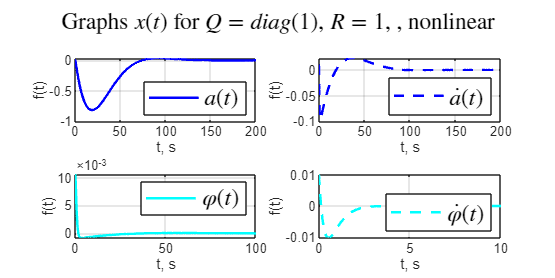



% Графики
figure('Position', [100 100 800 400])
subplot(2,2,1);
plot(t, x(:,1), 'b-', 'LineWidth',1.5); 
legend('$a(t)$','Interpreter','latex',  'FontSize', 14, 'Location', 'southeast')
ylabel('f(t)')
xlabel('t, s')
xlim([0 200])
grid()

%figure('Position', [100 100 800 400])
subplot(2,2,2);
plot(t, x(:,2), 'b--', 'LineWidth',1.5); 
legend('$\dot{a}(t)$','Interpreter','latex',  'FontSize', 14, 'Location', 'southeast')
ylabel('f(t)')
xlabel('t, s')
xlim([0 200])
grid()

subplot(2,2,3);
plot(t, x(:,3), 'c-', 'LineWidth',1.5); 
legend('$\varphi (t)$','Interpreter','latex',  'FontSize', 14, 'Location', 'northeast')
ylabel('f(t)')
xlabel('t, s')
xlim([0 100])
grid()

subplot(2,2,4);
plot(t, x(:, 4), 'c--', 'LineWidth',1.5);
legend('$\dot{\varphi}(t)$','Interpreter','latex',  'FontSize', 14, 'Location', 'southeast')
ylabel('f(t)')
xlabel('t, s')
xlim([0 10])
grid()

sgtitle('Graphs $x(t)$ for $Q=diag(1)$, $R=1$, , nonlinear','Interpreter','latex',  'FontSize', 14)
full_path = ['C:\Users\user\Desktop\STUDY_2.0\3 курс робототехника\6 семестр\ТАУ\TAU_\1_Course_Project\TAU_Course_Project\' ...
    'pic_fix\6_2_Q_1_R_1_x.png'];

exportgraphics(gcf, full_path, 'Resolution', 300);

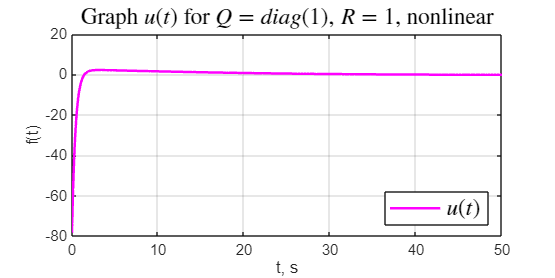




figure('Position', [100 100 800 400])
plot(t, u, 'm-', 'LineWidth',1.5);
legend('$u(t)$','Interpreter','latex',  'FontSize', 14, 'Location', 'southeast')
ylabel('f(t)')
xlabel('t, s')
xlim([0 50])
grid()


title('Graph $u(t)$ for $Q=diag(1)$, $R=1$, nonlinear','Interpreter','latex',  'FontSize', 14)
full_path = ['C:\Users\user\Desktop\STUDY_2.0\3 курс робототехника\6 семестр\ТАУ\TAU_\1_Course_Project\TAU_Course_Project\' ...
    'pic_fix\6_2_Q_1_R_1_u.png'];

exportgraphics(gcf, full_path, 'Resolution', 300);